# Anomaly Detection & Early Warning Systems

## How to use this live script

In this executable notebook (Live Editor) you have a logical track of the work, with working code snippets, some (non-binding) method suggestions.

Always remember: when it comes to data modeling, there is almost never a "one size fits all", thus you can take various ways to solve the problem.

So feel free to take this code as a draft, change it, even significantly, following your modeling vision. Feel free to explore data and methods and gain experience (yes, even getting it wrong and getting results you don't like - it's quite normal in real applications). You will find some "*HINTS*": they are just suggestions for you. Remember: experimenting with data - that's the purpose of this Machine Learning Lab.

## Goal: building an Early Warning System

First, we'll warm-up and familiarize with some key concepts with the help of some artificial data.

Then we'll apply these concepts to a real-world dataset (from Bloomberg). The data is anonymous, mostly clean and NOT transformed/normalized/scaled.

The dataset is called "EWS" and is conveniently saved as a .mat file, even if you have also the corresponding .xls file (which has a different name, sorry, "FinancialMarketData.xlsx)" that you can use to download data from Bloomberg, in case you have access to a Bloomberg terminal.

## An Early Warning System based on the idea of "Anomaly Detection"

Financial assets in the medium to long term tend to generate positive risk premiums - supported by basic economic principles, such as:

- For equities, the positive return on capital invested in business activities;

- For bonds, the remuneration for deprivation of money (and consumption) and for the risk of default.

However, financial markets are periodically subject to crises where asset returns do not follow these principles.

Thus, investors' appetites for risk rise and fall over time and so do the prices of financial assets.

Market jargon refers to "**risk-on**" and "**risk-off**" situations, respectively:

- In risk-on situations, investors have a high risk appetite and bid up the prices of risky assets in the market (equities, corporate bonds, riskier government bonds, most commodities, etc);

- In risk-off situations, investors become more risk-averse and sell risky assets, sending their prices lower, and have the tendency to gravitate toward lower-risk investments (cash, short term bonds of "safe" countries, sometimes gold, etc). This is a **high systemic risk** situation.

Financial institutions would like to be able to find out promptly if they are in a risk-on or risk-off situation.

To do this, we might consider:

- Risk-off period = abnormal;

- Risk-on period =  normal.

We can create a Machine Learning model that helps us to promptly identify periods of financial anomaly: that is, an Early Warning System based on Anomaly Detection.

It is just one of the possible methodologies that can be used (I am interested in showing it to you because it is based on a class of popular models in Machine Learning, those of Anomaly Detection). For a very large survey on, see: [https://www.treasury.gov/initiatives/wsr/ofr/Documents/OFRwp0001_BisiasFloodLoValavanis_ASurveyOfSystemicRiskAnalytics.pdf](https://www.treasury.gov/initiatives/wsr/ofr/Documents/OFRwp0001_BisiasFloodLoValavanis_ASurveyOfSystemicRiskAnalytics.pdf).

## Introduction to the idea of Anomaly Detection 

To start focusing on the idea of Anomaly Detection, we start on a dataset that will allow you to visualize what the algorithm is doing.This is a simple example using (low-dimension, 2D) artificial data, so we can control the situation and understand the problem.

#### Warm-up: some artificial data

We generate random variables, say investments returns, that follow a mixture of two bivariate Gaussian distributions.

First variable: "ordinary returns = non-anomalous data".

mu1 = [1 1];                 % Mean of the 1st component
sigma1 = [1.7 0.5; 0.5 1.9]; % Covariance of the 1st component
nobs1 = 1e4;

Second variable: "unusual returns = anomalies"

mu2 = [-5 -6];                  % Mean of the 2nd component
sigma2 = [4.5 0.95; 0.95 3.5];  % Covariance of the 2nd component
nobs2 = 40;

We generate an unequal number of observations from each component (10000 vs 40). Then we combine the two sets of random variables in an artificial sample of investment returns.

We create proper labels Y: we set Y = 1 if the data is anomalous, otherwise Y = 0.

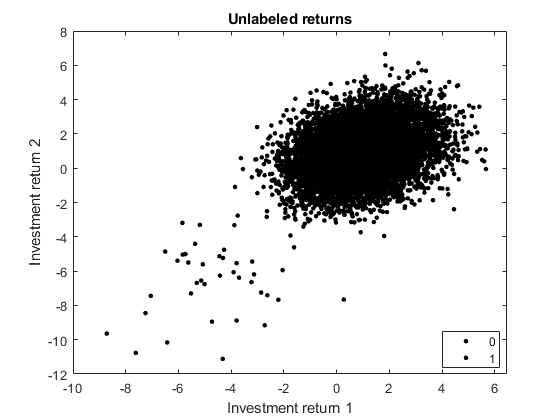

rng('default') % For reproducibility
r1 = mvnrnd(mu1,sigma1,nobs1);
r2 = mvnrnd(mu2,sigma2,nobs2);
X = [r1; r2];
Y = [zeros(nobs1,1); ones(nobs2,1)];

figure
gscatter(X(:,1),X(:,2), Y,'k', [],10)
xlabel('Investment return 1')
ylabel('Investment return 2')
title('Unlabeled returns')

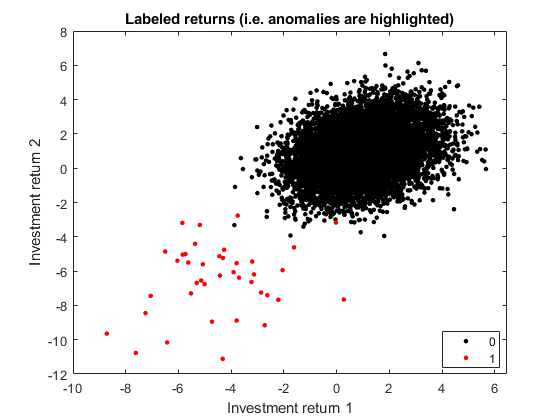

figure
gscatter(X(:,1), X(:,2), Y, ['k'; 'r'],[],10)
xlabel('Investment return 1')
ylabel('Investment return 2')
title('Labeled returns (i.e. anomalies are highlighted)')

**Our goal: ****learn to recognize anomalies****.**

### **Developing and Evaluating an Anomaly Detection System**

Just like in other learning problems, we are given a dataset of examples and responses, respectively, X, and Y (in this case, the artificial dataset). 

We define a "model" p(X), estimated from data, that tells us the probability that a new example is not anomalous;  that is, when we are given new data, we want to know whether this is abnormal - this is the prediction.

We use **a threshold ϵ (epsilon), which is an hyperparameter of the anomaly detection model**, as a dividing line.

So we can say which examples are anomalous and which are not: we identify unusual data by checking which have p(X)<ϵ.

#### Step1: creating training/cross-validation/test set

- We take our labeled data, categorized into anomalous and non-anomalous examples (Y = 0 if non-anomalous, Y = 1 if anomalous).

- We create: (1) a training set where we fit the parameters; (2) a cross-validation set, where we fine-tune the hyperparameter ϵ (epsilon); (3) a test set.

- In the artificial dataset we created, we have that about 0.40% of the data is anomalous and 99.60% is normal. Now, we take 60% of those examples, all of which are good (Y = 0) for the training set. We then take 20% of the examples for the cross-validation set (with 0.2% of the anomalous examples, Y = 1) and another 20% from the test set (with another 0.2% of the anomalous).

NOTE: Among that data, always take a large proportion of good, non-anomalous data for the training set on which to train p(X), without anomalous examples. In other words, we split the data 60/20/20 training/cross-validation/test set (or might be 70/15/15) and then split the anomalous examples 50/50 between the cross-validation and test sets.

% Please note: I don't reshuffle only because I know it's an artifical
% sample of i.i.d. observations, and I recreate the sample in an "ad hoc
% way" for the same reason
% Otherwise: reshuffle, always

XTrain = r1(1:6000,:);                     % 60% of X|Y=0
XCrossVal = [r1(6001:8000,:); r2(1:20,:)]; % 20% of X|Y=0 and 50% of X|Y=1
XTest = [r1(8001:end, :); r2(21:end,:)];   % 20% of X|Y=0 and 50% of X|Y=1
YCrossVal = zeros(length(XCrossVal),1);
YCrossVal(end-19:end) = 1;
YTest= zeros(length(XTest),1);
YTest(end-19:end) = 1;

#### Step 2: training the model

Let's model p(X) from the training set data:

- we must assume a multivariate distribution for our data;

- for the sake of simplicity, we assume it is a multivariate Gaussian distribution;

- we train the model, i.e., we estimate the parameters, the vector of means and the covariance matrix.

sigma = cov(XTrain);
mu = mean(XTrain);

#### Step 3: fine tuning the hyperparameter, the threshold ϵ

On the cross-validation set:

- We compute the probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ;

- If p(X) < ϵ (→ anomaly), then we predict Y = 1;

- If p(X) ≥ ϵ (→ normal), then we predict Y = 0;

- We select the value of ϵ that obtains the best score in terms of `[select the most appropriate metric according to the specific problem: F1 score, Precision, Recall, True positive, False positive, False negative, True negative]`.

- Usually the different values of epsilon are searched in the range [min(p(X), max(p(X)].

p = mvnpdf(XCrossVal,mu,sigma);

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

bestEpsilon = 0;
bestF1 = 0; %accuratezza del test bilenciando precisione e recupero

stepsize = (maxEpsilon - minEpsilon)/ 1000;
for epsilon = minEpsilon:stepsize:maxEpsilon

    predictions = p < epsilon;
    tp = sum((predictions == 1) & (YCrossVal == 1));
    fp = sum((predictions == 1) & (YCrossVal == 0));
    fn = sum((predictions == 0) & (YCrossVal == 1));
    prec = tp / (tp + fp);
    rec = tp / (tp + fn);
    F1 = 2 * prec * rec / (prec + rec);

    if F1 > bestF1
        bestF1 = F1;
        bestEpsilon = epsilon;
    end
end

bestF1

bestF1 = 0.9756

bestEpsilon

bestEpsilon = 9.3498e-05

For future work you can use this function: `OptimThreshold` (included); it works like this:

[bestEpsilon bestF1] = OptimThreshold(YCrossVal, p)

bestEpsilon = 9.3498e-05

bestF1 = 0.9756

#### Step 4: testing the model

On the test set:

- We compute the probability density function p(X) for each example in X;

- Using the optimal hyperparameter ϵ, we check if  p(X) < ϵ;

- If p(X) < ϵ (→ anomaly), then we predict Y = 1;

- If p(X) ≥ ϵ (→ normal), then we predict Y = 0;

- We compare our predictions with the ground truth (and we calculate usual performance metrics).

p = mvnpdf(XTest,mu,sigma);
predictions = p < bestEpsilon;
tp = sum((predictions == 1) & (YTest == 1));
fp = sum((predictions == 1) & (YTest == 0));
fn = sum((predictions == 0) & (YTest == 1));
prec = tp / (tp + fp)

prec = 0.9500

rec = tp / (tp + fn)

rec = 0.9500

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.9500

Some **useful references** for the basic idea of Anomaly Detection, see Andrew Ng [https://www.youtube.com/watch?v=g2YBWQnqOpw,](https://www.youtube.com/watch?v=g2YBWQnqOpw,) and also Chapter 10 of Tan, Steinbach, Kumar, (2014), "Introduction to Data Mining", Pearson New International Edition. 

## Real data for an Early Warning System

Now let's apply this probabilistic method to real data.

This is a dataset of financial data, representing a broad spectrum of features, that is, financial variables (e.g., interest rates, bond yields, bond indices, currencies, commodities, equity indices, implied volatility):

- From Bloomberg;

- Weekly data in local currency;

- In the original, raw format;

- Period = Jan-2000/Apr-2021.

The dataset contains also a **response variable, Y = 1, if market is abnormal/risk-off, Y = 0 otherwise**.

*HINTS*: You can create your own response variable, looking at the main financial crisis - see for example [https://en.wikipedia.org/wiki/List_of_stock_market_crashes_and_bear_markets;](https://en.wikipedia.org/wiki/List_of_stock_market_crashes_and_bear_markets;) also, interesting hints here: [https://www.docdroid.net/rXfIG62/long-term-asset-return-study-the-next-financial-crisis-db-pdf#page=2](https://www.docdroid.net/rXfIG62/long-term-asset-return-study-the-next-financial-crisis-db-pdf#page=2).

#### *Load data*

close all
clc
path = '/Users/veron/OneDrive - Politecnico di Milano/fintech/Lab/Zenti_BusinessCase3/EWS.mat';
load(path)

### A short data exploration

(You can spend days doing data exploration on this data...)

Let's start focusing on univariate data properties, randomly picking just a few variables from the dataset.

#### Univariate properties 

We begin with the response variable, Y, related to identifying abnormal periods.

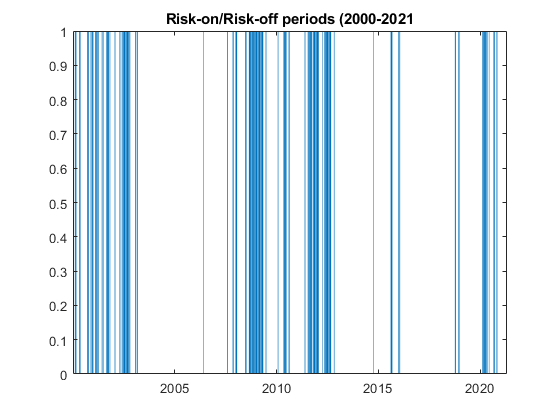

figure
bar(Data,Y)
title('Risk-on/Risk-off periods (2000-2021')

To better understand the labels of "anomalous market", we also plot the time series of the US equities (MSCI USA), well correlated with all the main stock exchanges in the world.

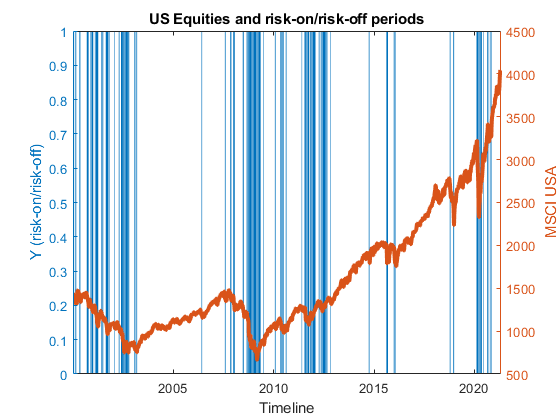

figure
yyaxis left
b = bar(Data,Y);
yyaxis right
p= plot(Data,MXUS);
p.LineWidth = 3;
title('US Equities and risk-on/risk-off periods')
xlabel('Timeline')
yyaxis left
ylabel('Y (risk-on/risk-off)')
yyaxis right
ylabel('MSCI USA')

Let's have a look at a bond yield, ie an interest rate: the Italian BTP 10Yrs (levels and first differences).

We want to understand:

- stationarity;

- shape of the distribution.

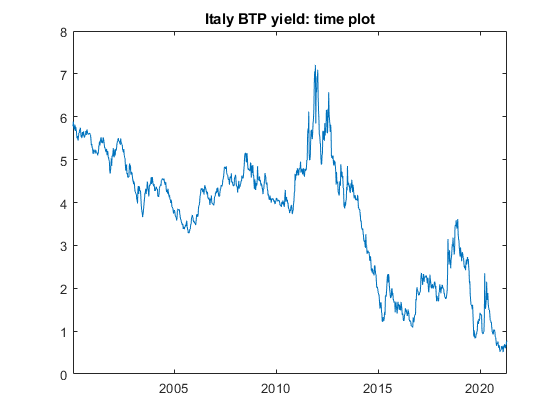

figure
plot(Data,GTITL10YR)
title('Italy BTP yield: time plot')

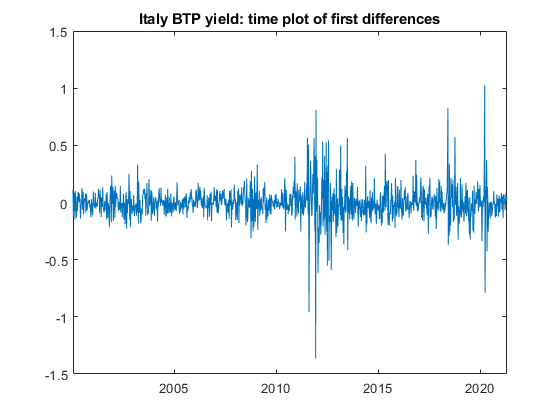

figure
plot(Data(2:end),diff(GTITL10YR))
title('Italy BTP yield: time plot of first differences')

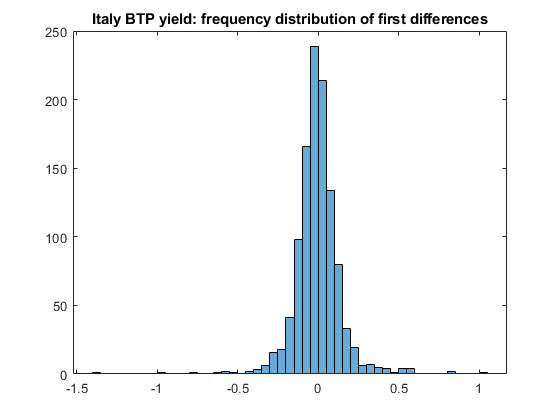

figure
histogram(diff(GTITL10YR))
title('Italy BTP yield: frequency distribution of first differences')

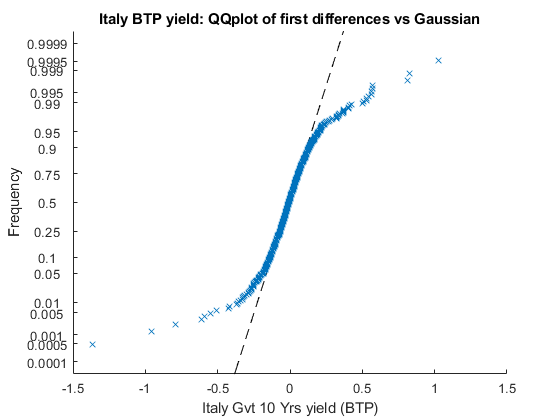

figure
probplot('normal',diff(GTITL10YR));figure(gcf)
title('Italy BTP yield: QQplot of first differences vs Gaussian')
xlabel('Italy Gvt 10 Yrs yield (BTP)')
ylabel('Frequency')

Now we esamine an equity asset, a market index: MSCI Europe (levels and first differences).

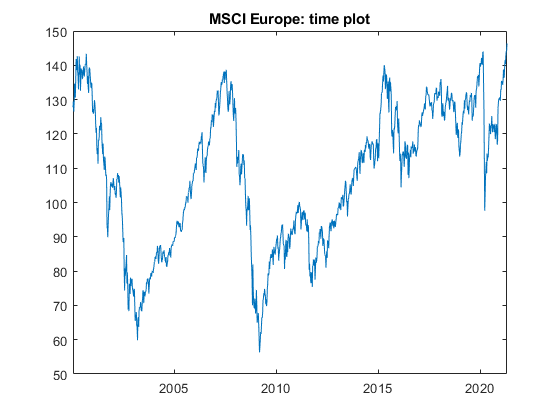

figure
plot(Data,MXEU)
title('MSCI Europe: time plot')

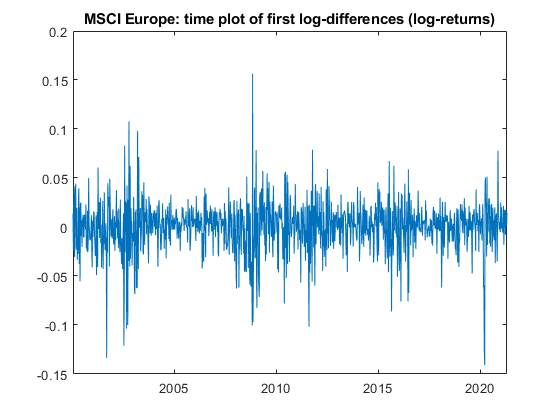

figure
plot(Data(2:end),diff(log(MXEU)))
title('MSCI Europe: time plot of first log-differences (log-returns)')

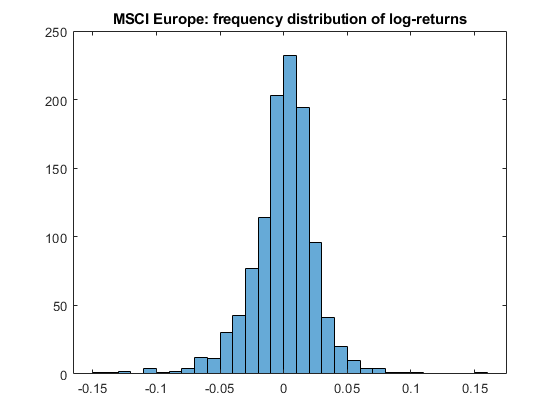

figure
histogram(diff(log(MXEU)))
title('MSCI Europe: frequency distribution of log-returns')

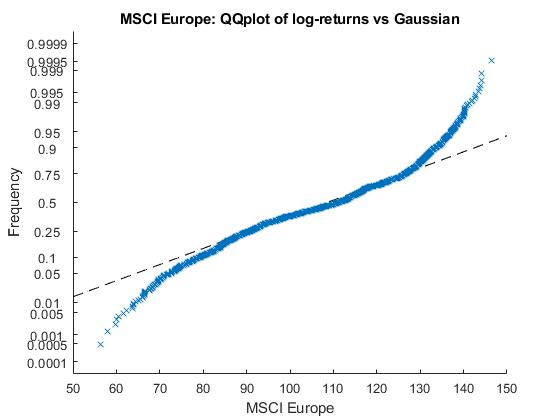

figure
probplot('normal',MXEU);figure(gcf)
title('MSCI Europe: QQplot of log-returns vs Gaussian')
xlabel('MSCI Europe')
ylabel('Frequency')

So we have fat-tailed (not-Gaussian), non-stationary data...(not a surprise).

The Bloomberg Economic US Surprise Index is roughly stationary (and we'll manage it as stationary).

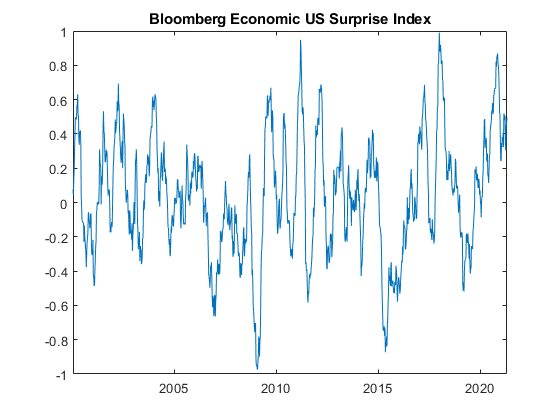

figure
plot(Data, ECSURPUS)
title('Bloomberg Economic US Surprise Index') %the only one stationary, it measures the positive unexpected good news

#### Coping with stationarity

Unless we use cointegration modeling, we need stationary data: this means that the joint distribution of the relevant variables must be stable over time.

The motivation for such an assumption is intuitive: we are attempting to use historical data to infer something about the structure of systemic risk, and if that structure is not stable over time, historical data may not be an accurate guide to what the future hold.

So, following the practice, we differentiate the features (not the label), keeping into account that some of them (interest rates) can take negative values - see the example below. The only exception is the Bloomberg Economic US Surprise Index.

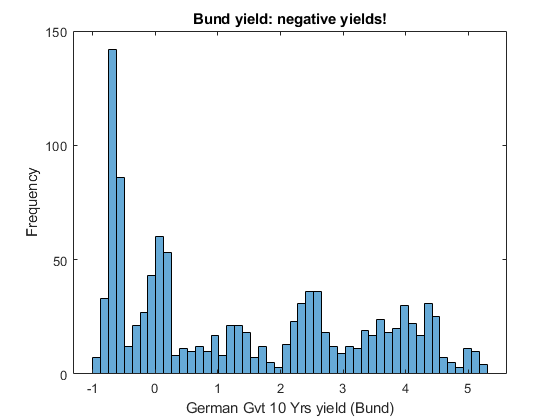

figure
histogram(GTDEM2Y, 50);
title('Bund yield: negative yields!')
xlabel('German Gvt 10 Yrs yield (Bund)')
ylabel('Frequency')

% % Always positive variables => log-differences (log-returns)
Indices_Currencies = [XAUBGNL BDIY CRY Cl1 DXY EMUSTRUU GBP JPY LF94TRUU LF98TRUU LG30TRUU LMBITR LP01TREU...
       LUACTRUU LUMSTRUU MXBR MXCN MXEU MXIN MXJP MXRU MXUS VIX];

% Possibly negative variables => first differences
InterestRates = [EONIA GTDEM10Y GTDEM2Y GTDEM30Y GTGBP20Y GTGBP2Y GTGBP30Y...
    GTITL10YR GTITL2YR GTITL30YR GTJPY10YR GTJPY2YR GTJPY30YR US0001M USGG3M USGG2YR GT10 USGG30YR];

Data = [diff(log(Indices_Currencies)) ECSURPUS(2:end) diff(InterestRates)]; % make stationary
Response = Y(2:end); % we lose one observation (the first)

### **Multivariate perspective**

Matrix of scatter plots comparing our Xs by using the our Y as grouping variable (I plot just a selection of features, and they are already too many).

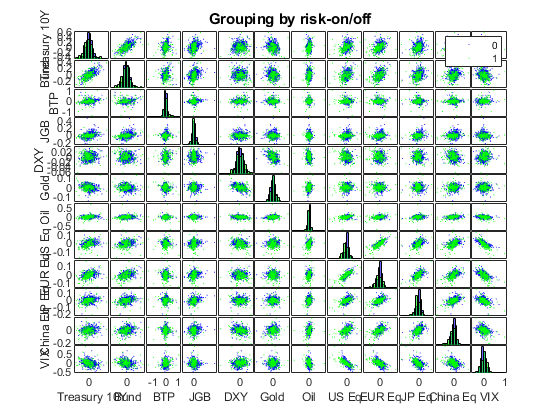

figure
Dat4Plot = [diff(GT10) diff(GTDEM10Y) diff(GTITL10YR) diff(GTJPY10YR)...
    diff(log(DXY)) diff(log(XAUBGNL)) diff(log(Cl1)) diff(log(MXUS))...
    diff(log(MXEU)) diff(log(MXJP)) diff(log(MXCN)) diff(log(VIX))];
xnames = {'Treasury 10Y', 'Bund', 'BTP', 'JGB', 'DXY', 'Gold', 'Oil', 'US Eq', 'EUR Eq', 'JP Eq', 'China Eq', 'VIX'};
gplotmatrix(Dat4Plot,[],Response, [],[],[],[],'grpbars', xnames)
title('Grouping by risk-on/off')

### **Developing and Evaluating an Anomaly Detection System**

Just like we did before using the artificial data...

A note on scaling/normalizing: generally, for this type of model it is not necessary to normalize or standardize the financial variables (they are dimensionally and semantically homogeneous), it is sufficient that they are stationary. But obviously it is necessary to carefully consider case by case, according to the data, the problem to be solved, the model to be used.

### Step1: creating training/cross-validation/test set

First we reshuffle.

Then we divide our data as follows:

- Training set = 80% of the examples, all of which are good (Y = 0)

- Cross-validation set = 10% of the examples such that Y = 0, and 50% of the anomalous examples, i.e. Y = 1;

- Test set = same as above.

I partion data directly, splitting features and responses, but you might find useful this function, `cvpartition`, that defines random partitions on a data set: [https://it.mathworks.com/help/stats/cvpartition.html.](https://it.mathworks.com/help/stats/cvpartition.html.) (And yes, naming convention can be improved...)

nObs = length(Response); % #data
nObsNorm = sum(Response == 0); % #normal data points
nObsAbNorm = nObs - nObsNorm; % #abnormal data points
nObsTrain = round(0.80*nObsNorm); % #length training set
nObsCVNorm = round(0.10*nObsNorm); % #length normal portion of CV set
nObsCVabNorm = round(nObsAbNorm/2); % #length abnormal portion of CV set
nObsTest_abNorm = nObsAbNorm - nObsCVabNorm; % #length abnormal portion of Train set

% Reshuffling the sample
idxPermutation = randperm(nObs);
X = Data(idxPermutation,:);
Response = Response(idxPermutation);

% dividing normal/abnormal
Xnormal = X(Response == 0,:);
Xabnormal = X(Response == 1,:);
Yabnormal = Response(Response == 1,:);

XTrain = Xnormal(1:nObsTrain,:);
XCV = [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,:); Xabnormal(1:nObsCVabNorm,:)];
XTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,:); Xabnormal(nObsCVabNorm+1:end,:)];

yCV = zeros(length(XCV),1);
yCV(end-nObsCVabNorm+1:end) = Yabnormal(1:nObsCVabNorm);
yTest = zeros(length(XTest),1);
yTest(end-nObsTest_abNorm+1:end) = Yabnormal(nObsCVabNorm+1:end);

#### Step 2: training the model

Let's model p(X) from the training set data:

- We still assume a multivariate Gaussian distribution for our data (even if we know that it's not true);

- We train the model, i.e., we estimate the parameters, the vector of means and the covariance matrix.

sigma = cov(XTrain);
sigma = 0.5*(sigma+sigma'); % ensures symmetry
mu = mean(XTrain);

#### Step 3: fine tuning the hyperparameter, the threshold ϵ

On the cross-validation set:

- We compute the probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ

- If p(X) < ϵ (anomaly), then Y = 1;

- If p(X) ≥ ϵ (normal), then Y = 0;

- We select the value of ϵ that obtains the best score in terms of `[select the most appropriate metric according to the specific problem: F1 score, Precision, Recall, True positive, False positive, False negative, True negative]`.

- Usually the different values of are in the range [min(p(X), max(p(X)].

p = mvnpdf(XCV,mu,sigma); % compute the probability density function for each example

[bestEpsilon, bestF1] = OptimThreshold(yCV, p) % find the optimal epsilon

bestEpsilon = 1.9119e+47

bestF1 = 0.7329

#### Step 4: testing the model

On the test set:

- We compute the probability density function p(X) for each example in X;

- Using the optimal hyperparameters ϵ, we check if  p(X) < ϵ;

- If p(X) < ϵ (anomaly), then we predict Y = 1;

- If p(X) ≥ ϵ (normal), then we predict Y = 0;

- We compare our predictions with the ground truth (and we calculate usual performance metrics).

p = mvnpdf(XTest,mu,sigma);
predictions = p < bestEpsilon;
tp = sum((predictions == 1) & (yTest == 1))

tp = 114

fp = sum((predictions == 1) & (yTest == 0))

fp = 86

fn = sum((predictions == 0) & (yTest == 1))

fn = 4

prec = tp / (tp + fp)

prec = 0.5700

rec = tp / (tp + fn)

rec = 0.9661

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7170

#### New data arrives...

Let's assume we are at the beginning of a week on the markets: all the updated data arrives (Asian closures, European market openings, etc.) and the question for the Early warning System is:

                                               * is a risk-on or a risk-off day?*

(Let's artificially define new fake data - for the sake of simplicity, we create them from existing data - sampling and averaging two points from, respectively, abnormal and normal data, and setting all the equity last week returns equal to -15% for the abnormal case.)

NewDataAbnormal = mean(Data(randi(length(X(Response == 1,:)),2,1), :));
NewDataAbnormal(16:22) = -0.15;
NewDataNormal = mean(Data(randi(length(X(Response == 0,:)),2,1), :));

Supposedly risk-off day:

p = mvnpdf(NewDataAbnormal,mu,sigma);
prediction = p < bestEpsilon;
if prediction
    'prediction = Abnormal'
else
    'prediction = Normal'
end

ans = 'prediction = Abnormal'

Supposedly risk-on day:

p = mvnpdf(NewDataNormal,mu,sigma); %???? should be normal
prediction = p < bestEpsilon;
if prediction
    'prediction = Abnormal'
else
    'prediction = Normal'
end

ans = 'prediction = Abnormal'

Not too bad, overall.

However, note that:

- the "anomaly" label has essentially been attributed to extremely negative markets;

- the multivariate probability density also signals abnormally good markets as anomalous.

To take this into account this asymmetry (it might be the case, or not, it depends...), various ways can be followed:

- segment the dataset into assets whose behavior is homogeneous (eg interest rates, risky asset indices, safest asset indices, etc.), using the Cumulative Distribution Function (the CDF, instead of the PDF), so we  check when Prob(x1< p, x2 < p,...), and obtain separate sub-scores to be combined in an aggregate score;

- use a discriminating variable, which separates abnormally positive situations from abnormally negative ones, for example an aggregate equity index (in bad situations equities tend to go down, overall) - kind of sanity check.

We will give a try to the latter approach; thus:

- we define a equally weighted global equity index, using a simple average of the equity assets in the dataset;

- we need it anly for cross-validation set and test set;

On the cross-validation set we use a slightly different procedure than before:

- We compute the probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ;

- If p(X) < ϵ (ie suspected anomaly), and the global equity index return is worse than **a given threshold T** (ie the equity market goes down), then Y = 1;

- Otherwise Y = 0;

- We define the threshold T as a percentile, based on a given probability pPercentile, that is:

                                                                        T = percentile(global equity index return, pPercentile);

- So we have another hyperparameter to be optimized, pPercentile;

- Basically we do a grid search on epsilon and pPercentile (ie a double loop);

- We select the value of ϵ that obtains the best score in terms of `[select the most appropriate metric according to the specific problem: F1 score, Precision, Recall, True positive, False positive, False negative, True negative]`.

Compute the "global equity index" equally weighting the 7 equity assets in our dataset (column 16:22 of the features' matrix).

% equity indices are column 16-22 (see above)
globalEquityCV = mean(XCV(:,16:22),2); % global equity index for the CV set
globalEquityTest = mean(XTest(:,16:22),2); % global equity index for the test set

Compute the probability density function for each example in the cross-validation set.

p = mvnpdf(XCV,mu,sigma);

Do the grid search over the parameter space of epsilon and pPercentile.

% Find the point in X with the greatest/smallest pdf value
maxEpsilon = max(p);
minEpsilon = min(p);

% Initialize accuracy metrics and hyperparameters
best_pPercentile = 0;
bestEpsilon = 0;
bestF1 = 0;
bestPrecision = 0;
bestRecall = 0;

%loop for pQuantile
for pPercentile = 1:1:99

    equityThreshold = prctile(globalEquityCV,pPercentile);

    % loop for epsilon
    stepsize = (maxEpsilon - minEpsilon)/ 1000;
    for epsilon = minEpsilon:stepsize:maxEpsilon

        predictions = (p < epsilon) & (globalEquityCV<equityThreshold);
        tp = sum((predictions == 1) & (yCV == 1));
        fp = sum((predictions == 1) & (yCV == 0));
        fn = sum((predictions == 0) & (yCV == 1));
        prec = tp / (tp + fp);
        rec = tp / (tp + fn);
        F1 = 2 * prec * rec / (prec + rec);

        if F1 > bestF1
            bestF1 = F1;
            bestPrecision = prec;
            bestRecall = rec;
            bestEpsilon = epsilon;
            best_pPercentile = pPercentile;
        end
    end
end

bestF1

bestF1 = 0.7313

bestPrecision

bestPrecision = 0.5821

bestRecall

bestRecall = 0.9832

bestEpsilon

bestEpsilon = 1.9119e+47

best_pPercentile

best_pPercentile = 99

Now, on the test set:

- We compute the probability density function p(X) for each example in X;

- Using the optimal hyperparameters ϵ, and bestpQuantile, we check if  p(X) < ϵ AND the global equity index return is worse than the threshold T = percentile(global equity index return, pQuantile);

- In that case our prediction is Y = 1;

- Otherwise the prediction is Y = 0;

- We compare our predictions with the ground truth (and we calculate usual performance metrics).

p = mvnpdf(XTest,mu,sigma);
equityThreshold = prctile(globalEquityTest,best_pPercentile);
predictions = (p < bestEpsilon) & (globalEquityTest<equityThreshold);
tp = sum((predictions == 1) & (yTest == 1))

tp = 113

fp = sum((predictions == 1) & (yTest == 0))

fp = 85

fn = sum((predictions == 0) & (yTest == 1))

fn = 5

prec = tp / (tp + fp)

prec = 0.5707

rec = tp / (tp + fn)

rec = 0.9576

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7152

The results on the test sample are roughly in line with the previous model: probably the idea of discriminating only on the basis of equity returns, even if it corresponds to financial intuition, does not capture the whole reality of the phenomenon, and it must be refined.

*HINTS*: you might refine this model, including variables with high signaling power, such as the VIX, or the BTP-Bund spread, or whatever you think can work.

*Note*: the general procedure based on estimating the probability density of a multivariate Gaussian distribution is essentially equivalent to using the Mahalanobis distance (see [https://it.mathworks.com/help/stats/mahal.html,](https://it.mathworks.com/help/stats/mahal.html,) and [https://en.wikipedia.org/wiki/Mahalanobis_distance](https://en.wikipedia.org/wiki/Mahalanobis_distance)). It can be shown that the Mahalanobis distance of a point to the mean of the distribution is related to the probability density associated to that point: Mahalanobis distance of point z = const + log(p(z)). So you could set-up an equivalent procedure using the Mahalanobis distance

## Using Copulas

In Machine Learning, the use of Copulas for Anomaly Detection is a relatively recent fact. But it is promising.

### A refresher on Copulas

Copulas are functions that describe dependencies among variables, and provide a way to create distributions that model correlated multivariate data. For a practical introduction see: [https://it.mathworks.com/help/stats/copulas-generate-correlated-samples.html.](https://it.mathworks.com/help/stats/copulas-generate-correlated-samples.html.)

From a theoretical refresher on Copulas, among the others, see (1) "A Short, Comprehensive, Practical Guide to Copulas" by A. Meucci (included in supplementary material); (2) [http://archiv.stochastik.uni-freiburg.de/homepages/schmidt/publications/TSchmidt_Copulas.pdf](http://archiv.stochastik.uni-freiburg.de/homepages/schmidt/publications/TSchmidt_Copulas.pdf); (3) [https://en.wikipedia.org/wiki/Copula_(probability_theory);](https://en.wikipedia.org/wiki/Copula_(probability_theory);) (4) [http://www.columbia.edu/~mh2078/QRM/Copulas.pdf](http://www.columbia.edu/~mh2078/QRM/Copulas.pdf).

#### The key point on Copulas

The idea is that you can construct a multivariate distribution by (1) specifying marginal univariate distributions, and then (2) choose a Copula to provide a correlation structure between variables. Therefore, in practice, a factorization of marginals and correlation is carried out, which are thus independently modeled, with great advantages from the point of view of the realistic representation of the data (think about it: there are many univariate distributions that represent the data, but relatively few multivariate).

Thus (leaving aside computational problem) Copulas are one of the greatest ideas of Probability Theory available to those who have to model heterogeneous multivariate phenomena, with fat tails and "strange" dependence relationships between variables (Copulas are perfect for those involved in financial markets).

Let's look at Copulas from a practical point of view, considering two assets, the BTP 10 Yrs, and the Bund (German Gvt. 10 Yrs).

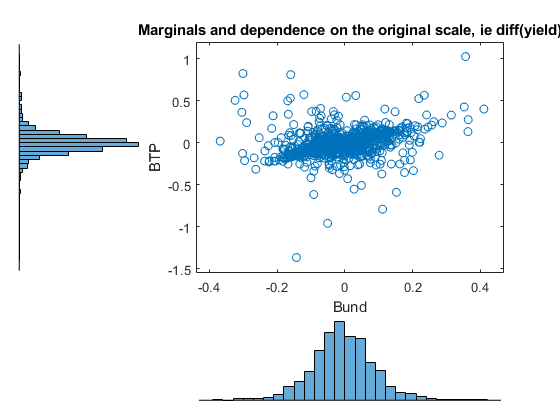

BTP = diff(GTITL10YR); % first differences for stationarity
Bund = diff(GTDEM10Y);
figure;
scatterhist(Bund,BTP)
title('Marginals and dependence on the original scale, ie diff(yield)')

Now,** transform the data from their original scale** (ie first differences of bond yields) **to the Copula scale** (ie unit square). We do that using a kernel estimator (see [https://it.mathworks.com/help/stats/ksdensity.html](https://it.mathworks.com/help/stats/ksdensity.html)) of the empirical cumulative distribution function (but you might use a parametric density function, eg GEVT, Weibull, t-student or whatever fits the data).

We plot:

- The CDFs,

- The relationship between CDFs, that is the empirical Copula (the data that we will use to estimate a parametric Copula), and its marginals.

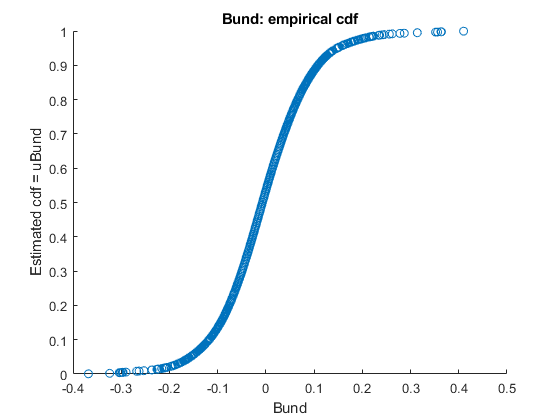

uBund = ksdensity(Bund,Bund,'function','cdf'); % 1st argument=>fit, 2nd=> specifies points to evaluate the CDF
uBTP = ksdensity(BTP,BTP,'function','cdf');

figure
scatter(Bund,uBund)
title('Bund: empirical cdf')
xlabel('Bund')
ylabel('Estimated cdf = uBund')

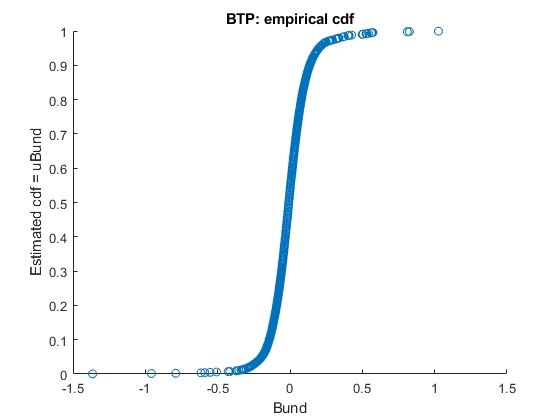

figure
scatter(BTP,uBTP)
title('BTP: empirical cdf')
xlabel('Bund')
ylabel('Estimated cdf = uBund')

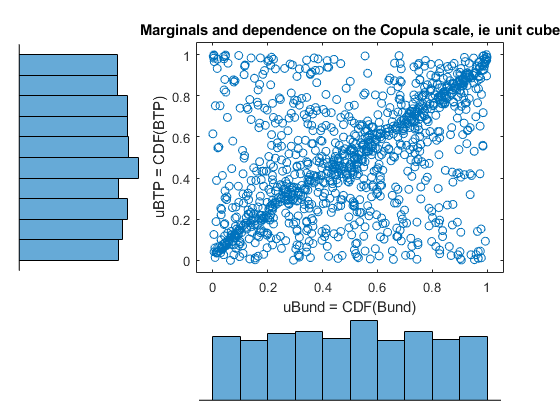

figure;
scatterhist(uBund,uBTP)
xlabel('uBund = CDF(Bund)')
ylabel('uBTP = CDF(BTP)')
title('Marginals and dependence on the Copula scale, ie unit cube')

Just note that the marginals of the Copula are uniform (this is the foundation of the Inverse Transformation Method for random sampling: [https://en.wikipedia.org/wiki/Inverse_transform_sampling](https://en.wikipedia.org/wiki/Inverse_transform_sampling)). 

**Now we fit a parametric Copula to tha data**, a t-Copula, that is - see [https://it.mathworks.com/help/stats/copulafit.html.](https://it.mathworks.com/help/stats/copulafit.html.)

Given the data in [`uBund uBTP, w`e get the two parameters that fully define a t-Copula:

- `Rho`, the matrix of correlation parameters;

- The degrees of freedom parameter, `nu`.

rng default  % For reproducibility
[Rho,nu] = copulafit('t',[uBund uBTP],'Method','ApproximateML')

Rho =     1.0000    0.5501
    0.5501    1.0000


nu = 1.6783

Note: if you want to examine the Kendall’s rank correlation, corresponding to the estimated *t* Copula you can use this command:

KendalTau = copulastat('t',Rho,nu)

KendalTau =     1.0000    0.3708
    0.3708    1.0000


Now we have estimated the Copula, which essentially is a multivariate density function over the CDFs of the original data.

A Copula has its CDF, and its PDF p(X): thus we can use this density function to evaluate abnormal events, like we did before with the multivariate Gaussian distribution - using the Copula density function, we can identify unusual data by checking which have p(X)<ϵ.

We plot the probability density function of the Copula as a surface. The function `copulapdf` (see [https://it.mathworks.com/help/stats/copulapdf.html](https://it.mathworks.com/help/stats/copulapdf.html)) returns the probability density of the *t* copula with the estimated correlation parameters, R`ho`, and degrees of freedom parameter, `nu`, evaluated at the points in `u `(which is the domain of the Copula, ie the unit square).

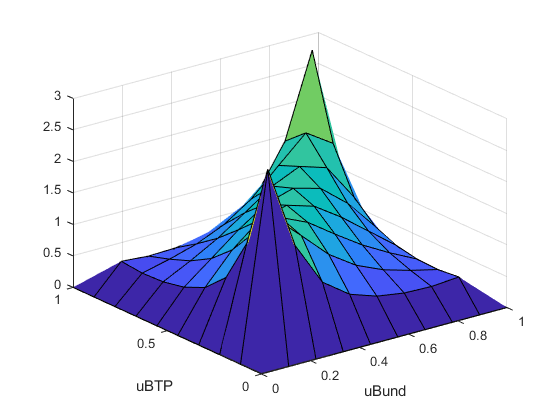

u = linspace(0,1,10);
[uCV,uTest] = meshgrid(u,u);
p = copulapdf('t',[uCV(:),uTest(:)],Rho,nu);
surf(uCV,uTest,reshape(p,10,10))
xlabel('uBund')
ylabel('uBTP')

*HINTS*:

- try different assets (instead of BTP 10 Yrs and Bund), just to see different copulas;

- try the Gaussian Copula, ie specify the copula type as 'Gaussian' in the function `copulafit`, and compare it to the t-student

#### *Digression - Bonus track (for those who know little about Copulas) *

#### How to generate a random sample from the *t* Copula (using the same data).

You can use a Copula to generate financial scenarios with a Monte Carlo simulation in which both marginal probability distributions and dependency relationships are modeled independently and with the utmost care in replicating reality, eg extreme events, non-linear correlation / tail dependence - please note: marginal distributions might be even all  of different types, to say...

Here we simulate random shocks (ie Δyield) on BTP and Bund.

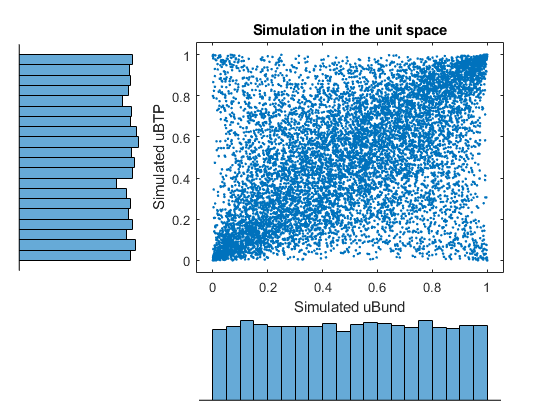

u = copularnd('t',Rho,nu,1e4);
sim_uBund = u(:,1);
sim_uBTP = u(:,2);

figure;
scatterhist(sim_uBund,sim_uBTP)
xlabel('Simulated uBund')
ylabel('Simulated uBTP')
set(get(gca,'children'),'marker','.')
title('Simulation in the unit space')

Transform the random sample back to the original scale of the data - an application of the Inverse Transform Method: from the unit square to the real world.

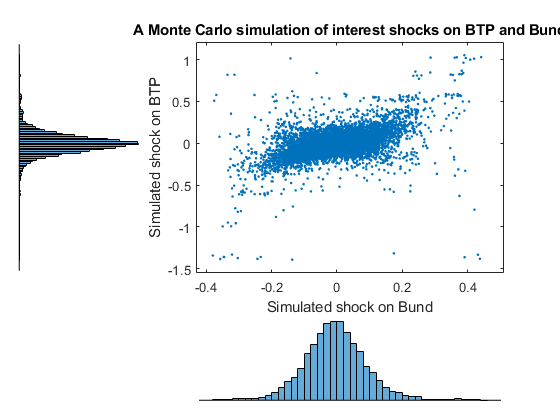

sim_Bund = ksdensity(Bund,sim_uBund,'function','icdf');  % 1st argument=>fit, 2nd=> specifies points to evaluate the ICDF
sim_BTP = ksdensity(BTP,sim_uBTP,'function','icdf');

figure;
scatterhist(sim_Bund,sim_BTP)
xlabel('Simulated shock on Bund')
ylabel('Simulated shock on BTP')
title('A Monte Carlo simulation of interest shocks on BTP and Bund')
set(get(gca,'children'),'marker','.')

#### *End-of-Digression*

#### ***End-of-Refresher on Copulas***

### Using Copulas to perform Anomaly Detection

The basic version of the process is indistinguishable, as far as the key steps are concerned, from the one used using the probability density function of a multivariate Gaussian: only, thanks to the Copula we are using a more realistic representation of reality.

To avoid an explosion in computation times (oh yes, welcome to the world of Copulas), we use a subset of financial assets - even if, using fewer assets, we have less information on possible outbreaks of systemic risk.

We keep the following assets: Gold, Oil (Futures), Japanese Yen, European equities, Russian equities, US equities, Japanese equities, VIX (Futures on the implied vol index), Bund, BTP 10 Yrs, the US Gvt 10 Yrs bond.

#### Training

On the training set we fit the Copula.

colSelector = [1 4 8 18 20 21 22 23 26 32 41]; % my selection of assets 
% Order: Gold Oil JPY EuEq EqRus USEq JPEq VIX Bund BTP10 TBond

[nSample, nFeatures] = size(XTrain(:,colSelector));
uTrain = zeros(nSample, nFeatures);

for i = 1:nFeatures
    uTrain(:,i) = ksdensity(XTrain(:,i), XTrain(:,i), 'function', 'cdf');
end

[rhohat0, nuhat0] = copulafit('t', uTrain); % fit Copula t

#### Cross-validation

On the cross-validation set we perform the usual operations:

- We compute the Copula probability density function p(X) for each example in X;

- For different values of ϵ we check if  p(X) < ϵ

- If p(X) < ϵ (anomaly), then Y = 1;

- If p(X) ≥ ϵ (normal), then Y = 0;

- We select the value of ϵ with the best score (here is F1, you can think differently).

[nSample, nFeatures] = size(XCV(:,colSelector));
uCV = zeros(nSample, nFeatures);

for i = 1:nFeatures
    uCV(:,i) = ksdensity(XCV(:,i), XCV(:,i), 'function', 'cdf');
end

p = copulapdf('t',uCV,rhohat0,nuhat0); % parameters estimated on the train set

[bestEpsilon, bestF1] = OptimThreshold(yCV, p) % find the optimal hyperparameter

bestEpsilon = 7.5603e+05

bestF1 = 0.7262

#### Test

We test the model, out-of-sample, on the test set.

[nSample, nFeatures] = size(XTest(:,colSelector));
uTest = zeros(nSample, nFeatures);

for i = 1:nFeatures
    uTest(:,i) = ksdensity(XTest(:,i), XTest(:,i), 'function', 'cdf');
end

p = copulapdf('t',uTest,rhohat0,nuhat0);

predictions = p < bestEpsilon;
tp = sum((predictions == 1) & (yTest == 1))

tp = 116

fp = sum((predictions == 1) & (yTest == 0))

fp = 87

fn = sum((predictions == 0) & (yTest == 1))

fn = 2

prec = tp / (tp + fp)

prec = 0.5714

rec = tp / (tp + fn)

rec = 0.9831

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7227

Again, not too bad.

Anyway, this is just a basic application of Copulas to Anomaly Detection in a supervised framework; for more advanced or different concepts, see [https://arxiv.org/pdf/1912.02166.pdf,](https://arxiv.org/pdf/1912.02166.pdf,) and above all (if interested in this topic) the unsupervised COPOD approach outlined here [https://arxiv.org/pdf/2009.09463.pdf.](https://arxiv.org/pdf/2009.09463.pdf.)

Using Copulas you can selectively look into the tails (which is the idea behind COPOD).

*HINTS*:

- Try fitting the Gaussian Copula (strongly suggested: it's faster, and usually it works well, even with big datasets);

- Try different set of assets;

- You might try to divide assets in a financially meaningful way - eg Set 1 = equities, Set 2 = interest rates, Set 3 = safe heavens (eg gold); then you could estimate different models for each set, using the Copula's CDF, not the PDF, searching in a predefined tail of the distribution, eg the left tail for equities, the right tail for gold, etc.

- If you want to go deeper into this topic, you might try using the COPOD approach, working separately on left and right tails (and skewness).

## Another HINT

## Unsupervised approach: using a Gaussian Mixture Model

In many practical situations, class labels are not available. Or, they are not reliable. So one might want to use an unsupervised approach: for example clustering.

We can imagine that there are two regimes, ie normal/abnormal, with two different covariances, two different vectors of means, and a mixing proportion. You can also imagine three regimes - but things can become tough from the computational point, which hopefully are very bad/normal/ very good.

So the typical process is:

- Estimate the model using `fitgmdist` `(`[https://it.mathworks.com/help/stats/fitgmdist.html](https://it.mathworks.com/help/stats/fitgmdist.html));

- Use **regularization** (like in a Lasso regression) to avoid badly conditioned covariance matrices: a Gaussian Mixture model has a lot of free parameters, and without any constraints on the parameter, estimation can be prohibitive from both a statistical and computational point of view - see [https://www.mitpressjournals.org/doi/pdf/10.1162/NECO_a_00128;](https://www.mitpressjournals.org/doi/pdf/10.1162/NECO_a_00128;) use a small positive value, eg 0.01, 0.02, 0.05,...;

- Usually financial data corresponds to distinct regimes - see the example below (I leave to you the possible exercise of evaluating the model on a historical basis) - but you never know, it's an undsupervised method, hence the data "self-organizes"...

- Assuming that you get two reasonable regimes, when new data arrives (e.g. opening of the markets on a given day), you assigne that day to the anomalous regime (risk-off) or to the normal one (risk-on), based on the highest posterior probability, ie argmax{posterior}`.`

- You can specify initial conditions, ie priors for means and covariances:`fitgmdist` fits GMMs to data using a Bayesian algorithm, the iterative *Expectation-Maximization* (EM) algorithm, so using wise initial values for component means, covariance matrices, and mixing proportions, the EM algorithm can converge better towards meaningful results. If you want to experiment with this method, I suggest you read it: [https://it.mathworks.com/help/stats/clustering-using-gaussian-mixture-models.html.](https://it.mathworks.com/help/stats/clustering-using-gaussian-mixture-models.html.)

Below a code snippet on the definition and estimation of a Gaussian Mixture Model.

lambda = 0.015; % regularization parameter
GMModel = fitgmdist(Data,2, 'RegularizationValue',lambda);
MixingProbability = GMModel.ComponentProportion

MixingProbability =     0.9613    0.0387


Means = GMModel.mu';
stdDev = [diag(GMModel.Sigma(:,:,1)) diag(GMModel.Sigma(:,:,2))];

Let's have a look at equity means and volatilities.

EquityMeans = exp(Means(16:22,:)*52)-1

EquityMeans =     0.1136   -0.8360
    0.0966   -0.5837
    0.0537   -0.6787
    0.1708   -0.7678
    0.0580   -0.6905
    0.1535   -0.8889
    0.0955   -0.6308


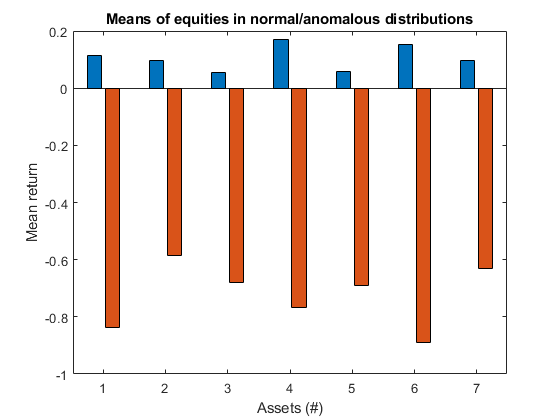

figure
bar(EquityMeans,'DisplayName','EquityMeans')
title('Means of equities in normal/anomalous distributions')
ylabel('Mean return')
xlabel('Assets (#)')

EquityVolatility = stdDev(16:22,:)*sqrt(52)

EquityVolatility =     0.1228    0.1825
    0.1171    0.1546
    0.1123    0.1275
    0.1160    0.1471
    0.1139    0.1324
    0.1246    0.2195
    0.1118    0.1232


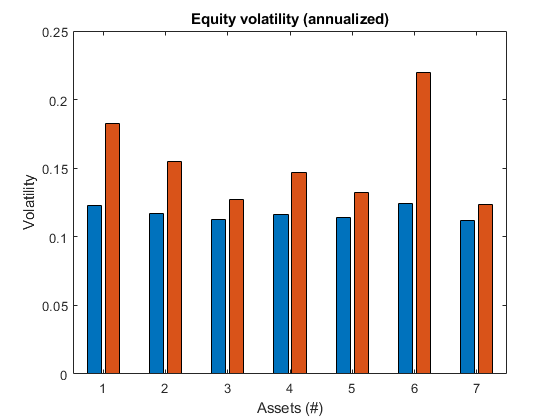

figure
bar(EquityVolatility,'DisplayName','EquityVolatility')
title('Equity volatility (annualized)')
ylabel('Volatility')
xlabel('Assets (#)')

#### New data arrives...

Like before: assume we are at the beginning of a week on the markets, all the updated data arrives and the question is:

                                               * is a risk-on or a risk-off day?*

(Again, let's artificially define new fake data - for the sake of simplicity, we create them from existing data - sampling and averaging two points from abnormal data, and setting all the equity last week returns equal to a huge negative value.)

NewDataAbnormal = mean(Data(randi(length(X(Response == 1,:)),2,1), :));
NewDataAbnormal(16:22) = -0.5;

This is clearly a risk-off day.

We compute the membership posterior probabilities or the data point using the fitted GMM. These probabilities represent cluster membership scores, and we select the cluster (normal or abnormal), using argmax{posterior}.

P = posterior(GMModel,NewDataAbnormal)

P =     0.0092    0.9908


My 2 cents - This method can perform really poorly on high dimensional data, so an accurate selection of financial variables can be of help.

*(Concluding) ****HINTS***: now you should have an idea of Anomaly detcion. So you might exploit some of the ideas presented here, or you might try a totally different approach, using techniques that you should know. For example:

- **Classification algorithms **(here the two classes, normal/abnormal, are imbalanced, but not that much, you can use oversampling/undersampling, SMOTE -see for example [https://github.com/dkbsl/matlab_smote/commit/30b525391df0f6e49cbff05ae4e0ec819c89beed](https://github.com/dkbsl/matlab_smote/commit/30b525391df0f6e49cbff05ae4e0ec819c89beed) and  [https://github.com/minoue-xx/Oversampling-Imbalanced-Data](https://github.com/minoue-xx/Oversampling-Imbalanced-Data));

- Also **simple (but astute) proximity-based algorithms **can work well, even a simple k-NN algorithm (compute distances between data points and associate index values — that can be used for detecting anomalies). One key idea is that a point is a market anomaly if is distant from an average market behaviour that you can estimate using a smart mixture of data mining/statistics and financial economics*, and the abnormal-score of the points might be its distance from that average market behaviour. So you have to identify a "normality vector" and use a distance metric...(without using an explicit probabilistic model);

- **Other unsupervised methods**, like **latent variable models**, starting from **PCA** - see for example [http://dx.doi.org/10.2139/ssrn.1582687;,](http://dx.doi.org/10.2139/ssrn.1582687;,) or **State-Space** (Kalman Filter) models;

- **Different methods can be combined** - Model Averaging Is Good (in general, I mean).

*Remember that using domain knowledge is always an advantage in any Data Science process.